## TOFデータの比較

１：rEMCL20 & nEMCL9とrEMCL20 & nEMCL1のTOFマップを比較する．

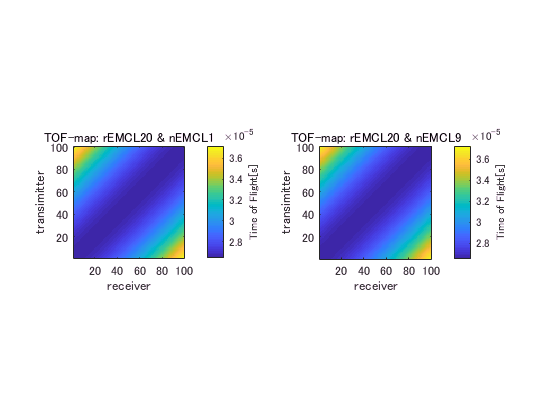

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_05_analyzePatternModel2')
load('rEMCL20 & nEMCL9')
tof_data_r20_n9 = tof_data;
load('rEMCL20 & nEMCL1')
tof_data_r20_n1 = tof_data;
figure;
subplot(1,2,1);
imagesc(1:100,1:100,tof_data_r20_n1(101:end,:));
xlabel('receiver')
ylabel('transimitter')
axis tight
axis equal
set(gca,'YDir','normal');
colorbar;
c = colorbar;
c.Label.String = 'Time of Flight[s]';
title('TOF-map: rEMCL20 & nEMCL1')

subplot(1,2,2);
imagesc(1:100,1:100,tof_data_r20_n9(101:end,:));
xlabel('receiver')
ylabel('transimitter')
axis tight
axis equal
set(gca,'YDir','normal');
title('TOF-map: rEMCL20 & nEMCL9')
colorbar;
c = colorbar;
c.Label.String = 'Time of Flight[s]';

２：最短パスをなす素子ペアをプロットし，

　　rEMCL20 & nEMCL9とrEMCL20 & nEMCL1で比較する．

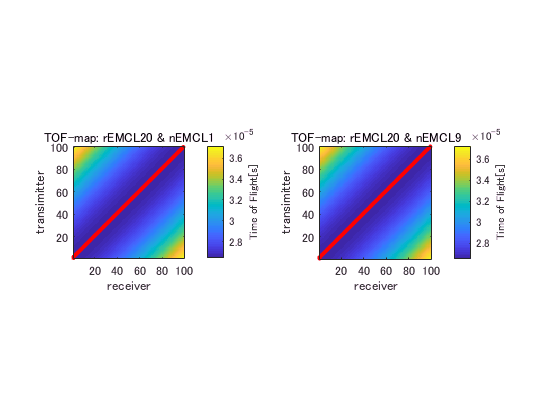

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_05_analyzePatternModel2')
load('rEMCL20 & nEMCL9')
tof_data_r20_n9 = tof_data;
load('rEMCL20 & nEMCL1')
tof_data_r20_n1 = tof_data;

figure;
subplot(1,2,1);
imagesc(1:100,1:100,tof_data_r20_n1(101:end,:));
hold on
[Min,ind]= min(tof_data_r20_n1(101:end,:));
for j = 1:100
    scatter(ind(1,j),j,10,'r','filled');
end
set(gca,'YDir','normal');
xlabel('receiver')
ylabel('transimitter')
axis tight
axis equal
title('TOF-map: rEMCL20 & nEMCL1')
colorbar;
c = colorbar;
c.Label.String = 'Time of Flight[s]';
hold off

subplot(1,2,2);
imagesc(1:100,1:100,tof_data_r20_n9(101:end,:));
hold on
[Min2,ind2]= min(tof_data_r20_n9(101:end,:));
for j = 1:100
    scatter(ind2(1,j),j,10,'r','filled');
end
set(gca,'YDir','normal');
xlabel('receiver')
ylabel('transimitter')
axis tight
axis equal
title('TOF-map: rEMCL20 & nEMCL9')
colorbar;
c = colorbar;
c.Label.String = 'Time of Flight[s]';
hold off

３：TOFマップの差分を表示し，rEMCL20 & nEMCL9　と　rEMCL20 & nEMCL1を比較する．

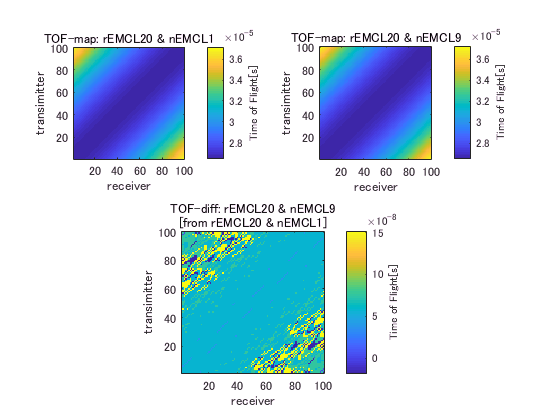

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_05_analyzePatternModel2')
load('rEMCL20 & nEMCL9')
tof_data_r20_n9 = tof_data;
load('rEMCL20 & nEMCL1')
tof_data_r20_n1 = tof_data;

figure;

subplot(2,2,1);
imagesc(1:100,1:100,tof_data_r20_n1(101:end,:));
[~,ind]= min(tof_data_r20_n1(101:end,:));
set(gca,'YDir','normal');
xlabel('receiver')
ylabel('transimitter')
axis tight
axis equal
title('TOF-map: rEMCL20 & nEMCL1')
colorbar;
c = colorbar;
c.Label.String = 'Time of Flight[s]';

subplot(2,2,2);
imagesc(1:100,1:100,tof_data_r20_n9(101:end,:));
set(gca,'YDir','normal');
xlabel('receiver')
ylabel('transimitter')
axis tight
axis equal
title('TOF-map: rEMCL20 & nEMCL9')
colorbar;
c = colorbar;
c.Label.String = 'Time of Flight[s]';

subplot(2,2,[3,4]);
imagesc(1:100,1:100,tof_data_r20_n9(101:end,:)-tof_data_r20_n1(101:end,:));
set(gca,'YDir','normal');
xlabel('receiver')
ylabel('transimitter')
axis tight
axis equal
title({'TOF-diff: rEMCL20 & nEMCL9'; '[from rEMCL20 & nEMCL1]'})
colorbar;
c = colorbar;
c.Label.String = 'Time of Flight[s]';

モード１：(tr, re) = (1,1) - (40,40)

モード２：(tr, re) = (41,41) - (100,100)

に分かれていそうだ．

４：TOFのヒストグラムでデータ比較を行う．分散分析などはせずに生データをヒストグラムプロット

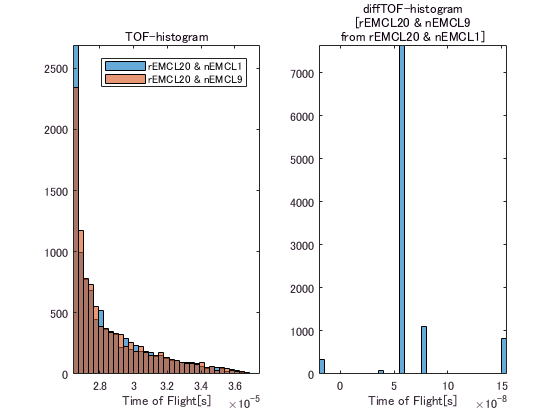

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_05_analyzePatternModel2')
load('rEMCL20 & nEMCL9')
tof_data_r20_n9 = tof_data;
tof_data_r20_n9 = reshape(tof_data_r20_n9(101:end,:),[1,100*100]);
load('rEMCL20 & nEMCL1')
tof_data_r20_n1 = tof_data;
tof_data_r20_n1 = reshape(tof_data_r20_n1(101:end,:),[1,100*100]);

figure;

subplot(1,2,1);
h1 = histogram(tof_data_r20_n1);
% h1.Normalization = 'probability'
hold on
h2 = histogram(tof_data_r20_n9);
% h2.Normalization = 'probability'
set(gca,'YDir','normal');
xlabel('Time of Flight[s]')
axis tight
title('TOF-histogram')
legend('rEMCL20 & nEMCL1','rEMCL20 & nEMCL9')
%なにかの分布にフィッティングできないか試してみる．
% mu1 = mean(c1);
% exp_pdf = @(t)(1/mu1)*exp(-t/mu1); % Integrates
%                                    % to 1
% t = 0:150;
% y = exp_pdf(t);
% plot(t,(hist_area)*y,'r','LineWidth',2)
hold off

subplot(1,2,2);
% h3 = histogram(tof_data_r20_n9);
h3 = histogram(tof_data_r20_n9 - tof_data_r20_n1);
% h3.Normalization = 'probability'
xlabel('Time of Flight[s]')
axis tight
title({'diffTOF-histogram';'[rEMCL20 & nEMCL9';'from rEMCL20 & nEMCL1]'})
hold off

% colorbar;
% c = colorbar;
% c.Label.String = 'Time of Flight[s]';

５：TOFデータを標準化してヒストグラムプロットで整理する．

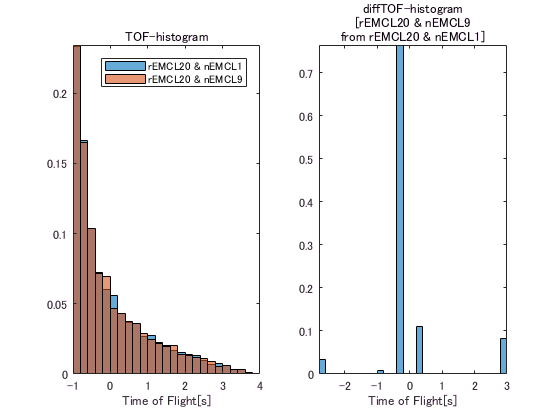

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_05_analyzePatternModel2')
load('rEMCL20 & nEMCL9')
tof_data_r20_n9 = tof_data;
tof_data_r20_n9 = reshape(tof_data_r20_n9(101:end,:),[1,100*100]);
load('rEMCL20 & nEMCL1')
tof_data_r20_n1 = tof_data;
tof_data_r20_n1 = reshape(tof_data_r20_n1(101:end,:),[1,100*100]);

figure;

subplot(1,2,1);
tof_data_r20_n1_2 = (tof_data_r20_n1 - mean(tof_data_r20_n1)) / std(tof_data_r20_n1);
h1 = histogram(tof_data_r20_n1_2);
h1.Normalization = 'probability';
hold on
tof_data_r20_n9_2 = (tof_data_r20_n9 - mean(tof_data_r20_n9)) / std(tof_data_r20_n9);
h2 = histogram(tof_data_r20_n9_2);
h2.Normalization = 'probability';
set(gca,'YDir','normal');
xlabel('Time of Flight[s]')
axis tight
title('TOF-histogram')
legend('rEMCL20 & nEMCL1','rEMCL20 & nEMCL9')
%指数分布にしたがうと予想される．フィッティングしてみる．
hold off

subplot(1,2,2);
% h3 = histogram(tof_data_r20_n9);
tof_diff = tof_data_r20_n9 - tof_data_r20_n1;
tof_diff_2 = (tof_diff - mean(tof_diff)) / std(tof_diff);
h3 = histogram(tof_diff_2);
h3.Normalization = 'probability';
xlabel('Time of Flight[s]')
axis tight
title({'diffTOF-histogram';'[rEMCL20 & nEMCL9';'from rEMCL20 & nEMCL1]'})
hold off

% colorbar;
% c = colorbar;
% c.Label.String = 'Time of Flight[s]';

６：素子間の距離を横軸に，縦軸に所要時間を入れてプロットする．

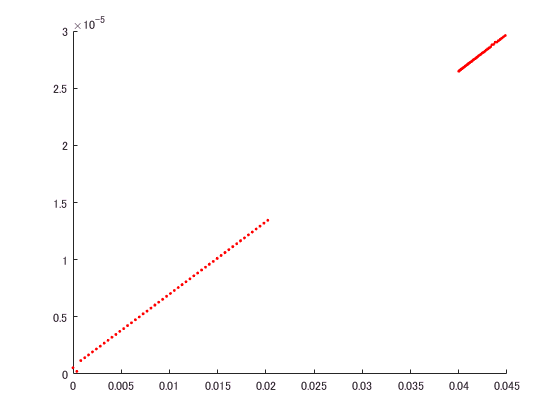

%まずはtofデータ一個を取り出して考える．
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_05_analyzePatternModel2')
load('rEMCL20 & nEMCL9')
tof_data_r20_n9 = tof_data;
[tof_x, tof_y] = size(tof_data_r20_n9);
%leng変数を使う．
leng = zeros(tof_x,tof_y);
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
for i = 1:t_num
    for j = 1:t_num/2
        leng(i,j) = sqrt((t_pos(1,i)-t_pos(1,j))^2+(t_pos(2,i)-t_pos(2,j))^2);
    end
end
tof_data_r20_n9 = cat(3,tof_data_r20_n9,leng);
%これでtofと素子間距離が対応付けられた．プロットする．
figure;
hold on
j = t_num/4;
for i = 1:t_num
    scatter(tof_data_r20_n9(i,j,2),tof_data_r20_n9(i,j,1),5,'ro','filled');
end
hold off

　あまり参考にならなそうだ．

　渡辺からアドバイスがあったのでやってみる．

７：素子番号を横軸に，速度を縦軸にとるグラフをプロットする．

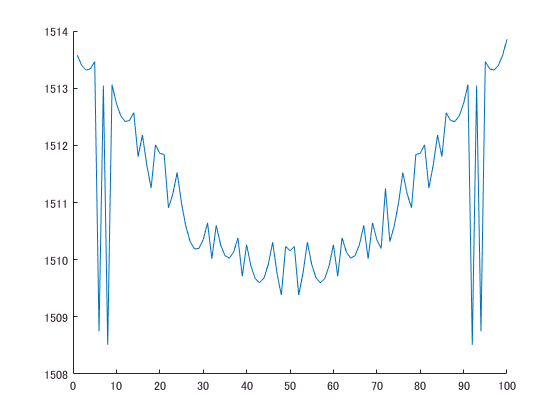

%まずはtofデータ一個を取り出して考える．
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_05_analyzePatternModel2')
load('rEMCL20 & nEMCL9')
tof_data_r20_n9 = tof_data;
[tof_x, tof_y] = size(tof_data_r20_n9);
%leng変数を使う．
leng = zeros(tof_x,tof_y);
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
for i = 1:t_num
    for j = 1:t_num/2
        leng(i,j) = sqrt((t_pos(1,i)-t_pos(1,j))^2+(t_pos(2,i)-t_pos(2,j))^2);
    end
end
v_r20_n9 = leng./tof_data_r20_n9;
%これでtofと素子間距離が対応付けられた．プロットする．
figure;
hold on
j = t_num/4;
plot(1:t_num/2,v_r20_n9(100+1:100+t_num/2,j));
hold off

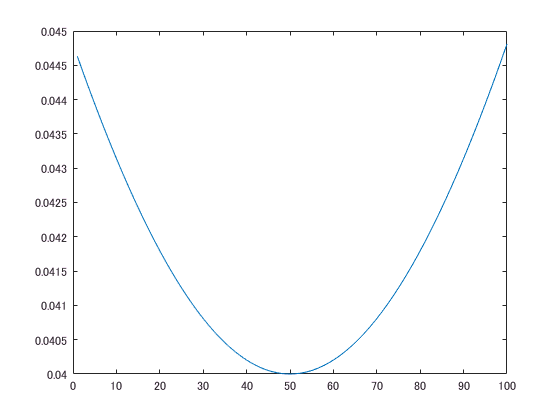

figure;
plot(leng(100+1:100+t_num/2,j));

v_muscle = 1580;%[m/s]
v_fat = 1450;%[m/s]
v = 1/((0.8/v_muscle)+(0.2/v_fat))

v = 1.5522e+03

結果が明らかにおかしい．普通は50chで音速最大になるはず．傾向が逆転しているし，まず1510 m/sあたりを示すのもおかしい．

８:EMCL0%のデータを用いて確認してみる．

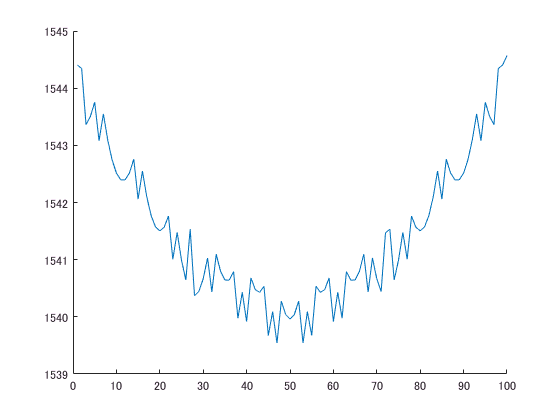

%まずはtofデータ一個を取り出して考える．
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_05_no_object')
load('NoObject')
tof_data_r0 = tof_data;
[tof_x, tof_y] = size(tof_data_r0);
%leng変数を使う．
leng = zeros(tof_x,tof_y);
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
for i = 1:t_num
    for j = 1:t_num/2
        leng(i,j) = sqrt((t_pos(1,i)-t_pos(1,j))^2+(t_pos(2,i)-t_pos(2,j))^2);
    end
end
v_r0 = leng./tof_data_r0;
%これでtofと素子間距離が対応付けられた．プロットする．

figure;
hold on
j = t_num/4;
plot(1:t_num/2,v_r0(100+1:100+t_num/2,j));
hold off

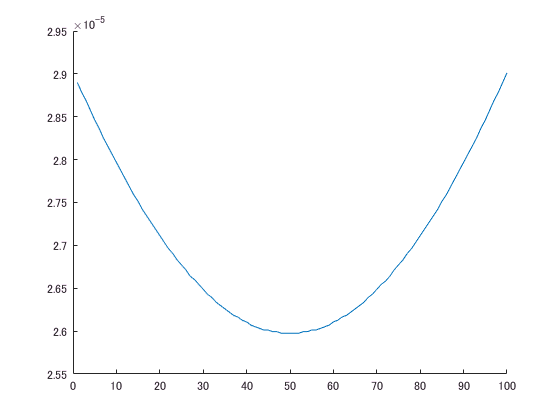

figure;
hold on
j = t_num/4;
plot(1:t_num/2,tof_data_r0(100+1:100+t_num/2,j));
hold off

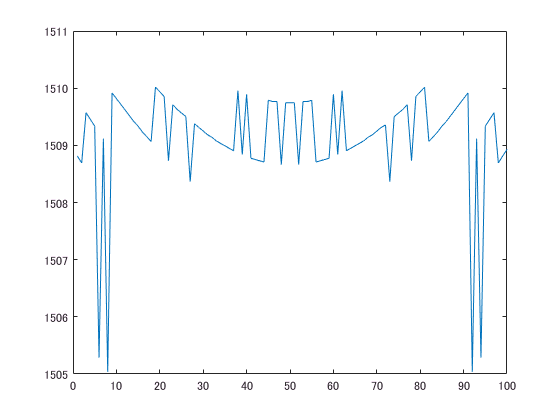

norm_v_r0 = v_r0(100+1:100+t_num/2,j)/min(v_r0(100+1:100+t_num/2,j));
j = t_num/4;
figure;
plot(1:t_num/2,v_r20_n9(100+1:100+t_num/2,j)./norm_v_r0);

均質媒質でこのように差が出るのはおかしい．この時点で1540 m/sあたりになっている．tof-map作成の時点でベースに誤差が含まれていると考えられる．

９：均質媒質のRFデータおよびTOFマップの確認

　どこにベースの誤差が含まれているのか明らかにする．

%まずはtofデータ一個を取り出して考える．
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_05_no_object')
load('NoObject')
tof_data_r0 = tof_data;
[tof_x, tof_y] = size(tof_data_r0);
%RFデータを読みこむ
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_05_no_object\NoObject')
load('rfdata.mat')
rfdata_no_object = rfdata;

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_05_no_object');
load('NoObject','tof_data')
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_05_no_object\NoObject');
load('kgrid')
kgrid.dt

ans = 1.8987e-08

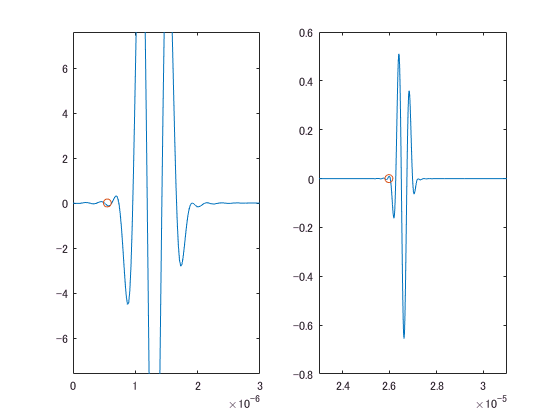

エラー: ylim (line 31)
範囲は増加する数値の 2 要素のベクトルでなければなりません。

tof_data_no_object = tof_data;
figure;
subplot(1,2,1)
plot(kgrid.t_array(1,:),rfdata_no_object(:,50,50));
hold on
scatter(tof_data_no_object(50,50),0);
hold off
subplot(1,2,2)
plot(kgrid.t_array(1,:),rfdata_no_object(:,150,50));
hold on
scatter(tof_data_no_object(150,50),0)
hold off

subplot(1,2,1)
xlim([-0.000000 0.000003])
ylim([-7.6 7.6])
subplot(1,2,2)
xlim([0.000023 0.000031])
ylim([-0.00 0.00])

AIC法がほぼ機能していないことが見て取れる．これがエラーの要因であると考えられる．

情けない...

しきい値法で対応する．均質媒質で，50ch-150chの音速をあわせこんで校正した．

次にEMCL20%の媒質でも同様に音速を確認する．

addpath(genpath('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\codes'))
v_muscle = 1580;%[m/s]
v_fat = 1450;%[m/s]
v = 1/((0.8/v_muscle)+(0.2/v_fat))

v = 1.5522e+03

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_05_patternScatter2')
cd('rEMCL20 & nEMCL1')
load('rfdata.mat')
load('kgrid.mat')

tof_map = threshold_picker(rfdata, kgrid);
v_cal = 40e-03/tof_map(150,50)

v_cal = 1.5524e+03

abs(v - v_cal)

ans = 0.2761

１サンプルずれると1.2 m/sずれることを踏まえると結果は良好とみなせる．

これでデータを組み直そう．

## RFデータの比較

平均音速値のモデルごとの比較をしたいが，2018/08/06 15:54現在データが揃っていないので，RFデータの比較をする．

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_05_patternScatter2')
cd('rEMCL20 & nEMCL1')
load('rfdata.mat')
rfdata_r20_n1 = rfdata;
cd('../rEMCL20 & nEMCL10')
load('rfdata.mat')
rfdata_r20_n10 = rfdata;
cd('../rEMCL2 & nEMCL1')
load('rfdata.mat')
rfdata_r2_n1 = rfdata;
cd('../rEMCL2 & nEMCL10')
load('rfdata.mat')
rfdata_r2_n10 = rfdata;

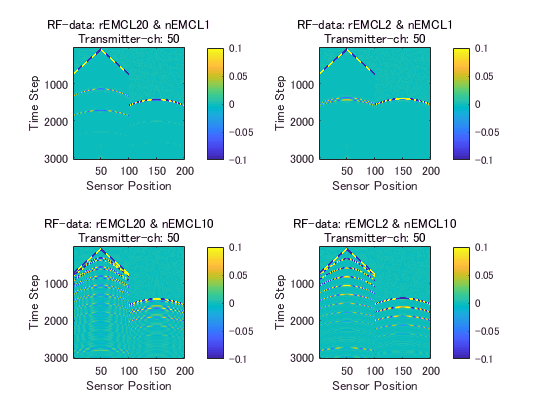

%% 50ch同士で並べて表示させる．
figure;
subplot(2,2,1);
imagesc(rfdata_r20_n1(:,:,50),[-0.1 0.1]);
xlabel('Sensor Position');
ylabel('Time Step');
colorbar;
title({'RF-data: rEMCL20 & nEMCL1';'Transmitter-ch: 50'})
axis square
axis tight

subplot(2,2,2);
imagesc(rfdata_r2_n1(:,:,50),[-0.1 0.1]);
xlabel('Sensor Position');
ylabel('Time Step');
colorbar;
title({'RF-data: rEMCL2 & nEMCL1';'Transmitter-ch: 50'})
axis square
axis tight

subplot(2,2,3);
imagesc(rfdata_r20_n10(:,:,50),[-0.1 0.1]);
xlabel('Sensor Position');
ylabel('Time Step');
colorbar;
title({'RF-data: rEMCL20 & nEMCL10';'Transmitter-ch: 50'})
axis square
axis tight

subplot(2,2,4);
imagesc(rfdata_r2_n10(:,:,50),[-0.1 0.1]);
xlabel('Sensor Position');
ylabel('Time Step');
colorbar;
title({'RF-data: rEMCL2 & nEMCL10';'Transmitter-ch: 50'})
axis square
axis tight

## 平均音速値のモデルごとの比較

１：全モデルでの平均音速値をプロットする．ここで構造の影響が大きく出ているデータを目視で特定する．

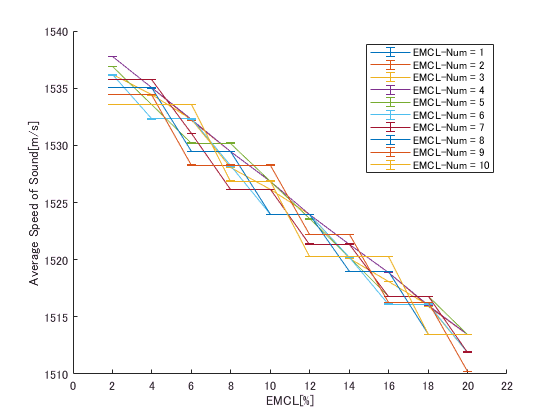

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_05_analyzePatternModel2')
load('2018_08_06_aveSOS&steSOS_1-10')
[~, num_pattern] = size(aveSOS);
figure;
hold on
x = [2 4 6 8 10 12 14 16 18 20];
for i = 1:num_pattern
    errorbar(x, aveSOS(x,i), 2*steSOS(x,i));
%     legend(['EMCL-Num = ' num2str(i) ''])
end
xlabel('EMCL[%]');
ylabel('Average Speed of Sound[m/s]')
xlim([0 22])
lgd = legend('EMCL-Num = 1','EMCL-Num = 2','EMCL-Num = 3','EMCL-Num = 4','EMCL-Num = 5',...
             'EMCL-Num =おん 6','EMCL-Num = 7','EMCL-Num = 8','EMCL-Num = 9','EMCL-Num = 10');

　煩雑すぎて何がなんやら．階段状になっている箇所があったので確認してみると，EMCL-Numが多すぎて，EMCL一個あたりの面積増加分が，mediumで設定したグリッドの解像度よりも微小な変化になったために，全く同じ媒質としてシミュレーションされてしまったケースが含まれていることが原因と考えられる．

　なので，”階段現象”が発生しないようにデータを飛ばし飛ばしで参照してプロットすることにした．

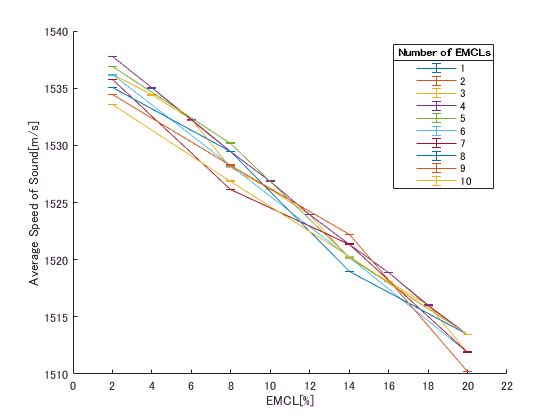

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_05_analyzePatternModel2')
load('2018_08_06_aveSOS&steSOS_1-10')
figure;
hold on
x = [2 4 6 8 10 12 14 16 18 20];
for i = 1:4
    errorbar(x, aveSOS(x,i), 2*steSOS(x,i));
end
x2 = [2 8 14 20];
for i = 5:10
    errorbar(x2, aveSOS(x2,i), 2*steSOS(x2,i));
end

xlabel('EMCL[%]');
ylabel('Average Speed of Sound[m/s]')
xlim([0 22])
lgd = legend('1','2','3','4','5',...
             '6','7','8','9','10');
title(lgd,'Number of EMCLs')

% v_muscle = 1580;%筋肉の音速[m/s]
% v_fat = 1450;%脂肪の音速[m/s]
% aveSOS_simple = zeros(20,1);
% for i = 2:2:20
%     aveSOS_simple(i,1) = v_fat*i/100 + v_muscle*(1-i/100);
% end
% plot(x,aveSOS_simple(x));
% lgd2 = legend('Average Speed of Sound from Area Ratio');

　モデルごとのプロットでは互いに交差しはするものの，平均音速値はおおよそ同じような傾向を持っていることが認められる．

　この10本のデータをまとめて，分散がわかるようなプロットにして，一覧性を高めるとともに，構造の複雑になることで平均音速値がどれだけ影響を受けるのかを評価できるようにする．

 ※EMCLの占有面積比から求めた音速値は0%のとき1580 m/sであることを踏まえれば，今回定義した最速パスに基づく平均音速値との差が大きい．おそらく伝播経路を直線と仮定したため，経路長が実際の屈折の影響を受けて折れた経路の全長よりも短く見積もられたためであると考えられる．

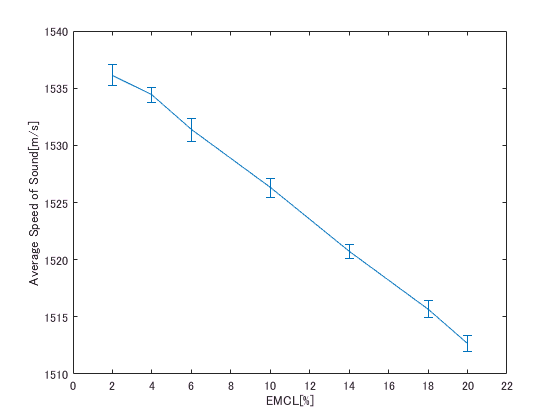

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_05_analyzePatternModel2')
load('2018_08_06_aveSOS&steSOS_1-10')
[num_EMCLrate, num_pattern] = size(aveSOS);
x = [2 4 6 8 10 12 14 16 18 20];
%steSOSは使わず，aveSOSだけを用いる
ave_aveSOS = mean(aveSOS,2);
ste_aveSOS = zeros(num_EMCLrate,1);
for i = 1:num_EMCLrate
    ste_aveSOS(i,1) = std(aveSOS(i,:))/sqrt(num_pattern);
end
x2 = [2 4 6 10 14 18 20];
for i = 1:num_pattern
%     plot(x2, ave_aveSOS(x2,1));
%     area(x2, [ave_aveSOS(x2,1)-2*ste_aveSOS(x2,1),ave_aveSOS(x2,1)+2*ste_aveSOS(x2,1)]);
    errorbar(x2, ave_aveSOS(x2,1), 2*ste_aveSOS(x2,1));
end

xlabel('EMCL[%]');
ylabel('Average Speed of Sound[m/s]')
xlim([0 22])

## 仮説

　全く同じaveSOSが算出された原因：mediumの微小変化がmediumの分解能では表現できなくなったため

## 方法

　RFデータの差分をとって検証する．

　１－rateEMCL: 4 %, numEMCL: 6

　２－rateEMCL: 6 %, numEMCL: 6

　TOFデータの差分をとって検証する．

## 結果

　差分の合計がRFデータ，TOFデータともに０になった．

　全く同じ媒質とみなしてシミュレーションが行われたと言える．

## 考察

　対策としてはさらにグリッドを細かくすることが考えられるが時間がかかりすぎる．一部データを参考にしないことで計算誤差をとりはらうことにする．

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_05_patternScatter2')
cd('rEMCL4 & nEMCL6')
load('rfdata.mat')
rfdata_r4_n6 = rfdata;
cd('../rEMCL6 & nEMCL6')
load('rfdata.mat')
rfdata_r6_n6 = rfdata;

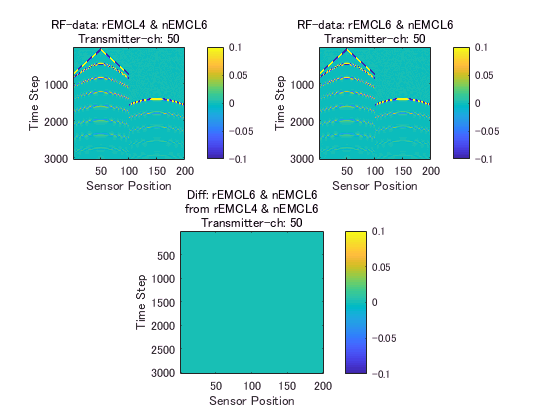

%% 50ch同士で並べて表示させる．
figure;
subplot(2,2,1);
imagesc(rfdata_r4_n6(:,:,50),[-0.1 0.1]);
xlabel('Sensor Position');
ylabel('Time Step');
colorbar;
title({'RF-data: rEMCL4 & nEMCL6';'Transmitter-ch: 50'})
axis square
axis tight

subplot(2,2,2);
imagesc(rfdata_r6_n6(:,:,50),[-0.1 0.1]);
xlabel('Sensor Position');
ylabel('Time Step');
colorbar;
title({'RF-data: rEMCL6 & nEMCL6';'Transmitter-ch: 50'})
axis square
axis tight
subplot(2,2,[3,4]);
imagesc(rfdata_r6_n6(:,:,50)-rfdata_r4_n6(:,:,50),[-0.1 0.1]);
xlabel('Sensor Position');
ylabel('Time Step');
colorbar;
title({'Diff: rEMCL6 & nEMCL6';'from rEMCL4 & nEMCL6';'Transmitter-ch: 50'})
axis square
axis tight

diff_rfdata = sum(sum(rfdata_r6_n6(:,:,50)-rfdata_r4_n6(:,:,50)));
diff_rfdata

diff_rfdata = 0

完全に同じrfデータでありそうだ．

最後にTOFマップの差分をとってみる．

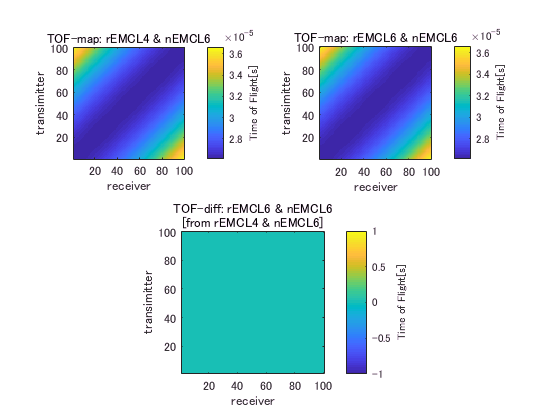

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_05_analyzePatternModel2')
load('rEMCL6 & nEMCL6')
tof_data_r6_n6 = tof_data;
load('rEMCL4 & nEMCL6')
tof_data_r4_n6 = tof_data;
figure;

subplot(2,2,1);
imagesc(1:100,1:100,tof_data_r6_n6(101:end,:));
[~,ind]= min(tof_data_r4_n6(101:end,:));
set(gca,'YDir','normal');
xlabel('receiver')
ylabel('transimitter')
axis tight
axis equal
title('TOF-map: rEMCL4 & nEMCL6')
colorbar;
c = colorbar;
c.Label.String = 'Time of Flight[s]';

subplot(2,2,2);
imagesc(1:100,1:100,tof_data_r6_n6(101:end,:));
set(gca,'YDir','normal');
xlabel('receiver')
ylabel('transimitter')
axis tight
axis equal
title('TOF-map: rEMCL6 & nEMCL6')
colorbar;
c = colorbar;
c.Label.String = 'Time of Flight[s]';

subplot(2,2,[3,4]);
imagesc(1:100,1:100,tof_data_r6_n6(101:end,:)-tof_data_r4_n6(101:end,:));
set(gca,'YDir','normal');
xlabel('receiver')
ylabel('transimitter')
axis tight
axis equal
title({'TOF-diff: rEMCL6 & nEMCL6'; '[from rEMCL4 & nEMCL6]'})
colorbar;
c = colorbar;
c.Label.String = 'Time of Flight[s]';

diff_tofdata = sum(sum(tof_data_r6_n6-tof_data_r4_n6));
diff_tofdata

diff_tofdata = 0

ここまで仮説から結論までの一セット．

媒質を比べてみることもできる．

## RFデータ解析

　EMCLの個数が変わると波形にどのような影響があるのかを確認する．